# Control design using state feedback

In this exercise we will design a controller for controlling the speed of a DC motor. 

## Physcial setup

- A common actuator in control systems is the DC motor. It directly provides rotary motion and, coupled with wheels or drums and cables, can provide translational motion.

- The electric equivalent circuit of the armature and the free-body diagram of the rotor are shown in the following figure.

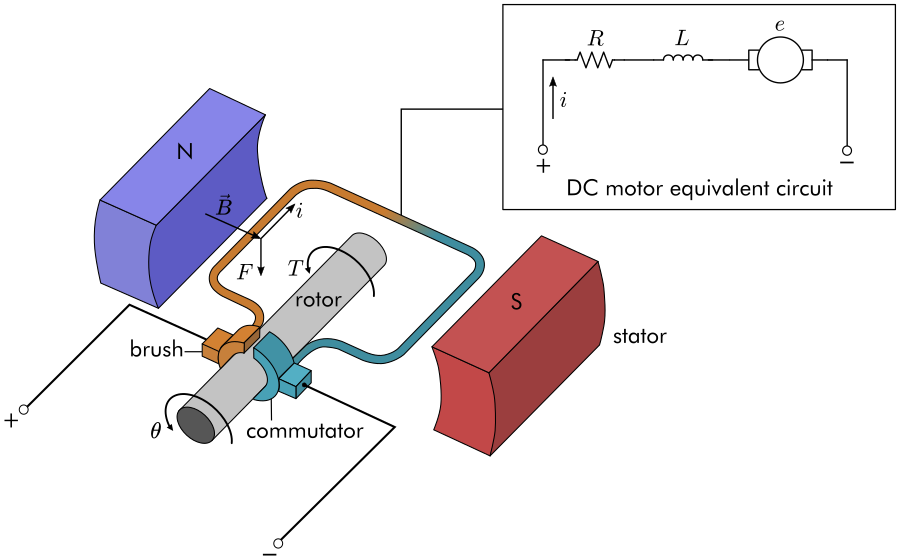

## System equations

- We can derive the following governing equations based on Newton's 2nd law and Kirchhoff's voltage law.


$$iR + L \frac{di}{dt} + k_e \dot{\theta} = v$$


 
$$J \ddot{\theta} + b \dot{\theta}  = k_m i$$
      

We will assume $K = k_e = k_m$

## State space model

- The armature voltage is treated as the input and the rotational speed is chosen as the output

- The state-space representation is therefore:

State vector: $\mathbf{x} = \left[ \begin{array}{c} 
\dot{\theta} \\
i

\end{array} \right]$


$$\dot{\mathbf{x}}  = \left[ \begin{array}{c} 
\ddot{\theta} \\
\dot{i}
\end{array} \right]   =  \left[ \begin{array}{cc}
-\frac{b}{J} &  \frac{K}{J} \\
-\frac{K}{L} & -\frac{R}{L} 
\end{array} \right] \left[ \begin{array}{c} 
\dot{\theta} \\
i
\end{array} \right]

  +  \left[ \begin{array}{c} 
0 \\
\frac{1}{L}  
\end{array} \right] v  \\ 
\dot{\mathbf{x}} = A\mathbf{x}  + Bu$$



$$y = \left[ \begin{array}{cc} 1 & 0 \end{array} \right] 
\left[ \begin{array}{c} 
\dot{\theta} \\ 
i
\end{array} \right] \\

y = C\mathbf{x} + Du$$


## System analysis

J = 0.01; %kg.m^2
b = 0.1; %N.m.s 
K = 0.01; %V/rad/s
R = 1; %Ohm
L = 0.5; %H


%setting up the state space model 
A = NaN; 
B = NaN; 
C = NaN;
D = NaN; 
dcMotorSS = ss(A,B,C,D); 

pole(dcMotorSS)
%Inspect characteristics of step response. 
linearSystemAnalyzer(dcMotorSS)

## Design requirements

First consider that our uncompensated motor rotates at 0.1 rad/sec in steady state for an input voltage of 1 Volt. 

- Settling time less than 2 seconds 

- Overshoot less than 5% (excess speed over reference can damage the motor) 

- Steady-state error less than 1% (because we want to maintain a constant speed) 

## Designing the full-state feedback controller

- Since both of the state variables in our problem are easy to measure (simply add an ammeter for current and a tachometer for the speed), we can design a full-state feedback controller (more information is better than less)

### Design methodology

- Unlike the case of PID control where the feedback was just the output, in state feedback control, we use the entire state as the feedback as shown in the figure below. 

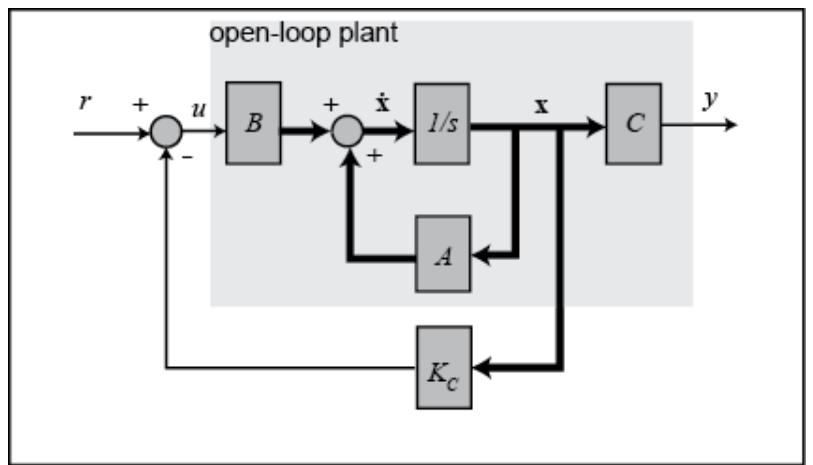

- Note that since $\mathbf{x}$ is a column vector, the feedback gain $K_c$ is a row vector. For the general case of multiple input systems, $K_c$ is a matrix. 

- Previously, the reference input $r$ was equal to the input $u$. But with the state feedback the new input is $u = r - K_c\mathbf{x}$

- We can subsitute this back into the state equation


$$\dot{\mathbf{x}} = A\mathbf{x}  + Bu \\
= A\mathbf{x}  + B(r - K_c\mathbf{x}) \\
= (A-BK_c)\mathbf{x} + Br$$


- The output equation remains the same.

- We previously saw that the poles of the system are equal to the eigenvalues of the state transition matrix. 

- Note that the state transition matrix changed from $A$ to $A-BK_c$. The latter will have different eigenvalues than $A$.

- The response of the system depends on the specific locations of the poles. By adjusting the values in the gain vector $K_c$, we can place the poles of the new system to obtain the desired resonse. 

- So, the next steps are 1) figure out where to place the poles, 2) adjust $K_c$ so that the eigenvalues of $A-BK_c$ are at the desired poles of the system. 

### Pole locations and system's response

theta = 1.77;
p1 = -5*exp(1j*theta); 
testTF = tf(20, [1, 2*real(p1), abs(p1)^2]); 
subplot(1,2,1); 
pzplot(testTF)
ylim([-5,5]); xlim([-6,1])
subplot(1,2,2)
step(testTF,3)

**Reflect:**

As the poles move toward the x-axis

- What is happening to the rise time? 

- What is happening to the overshoot? 

**Enter your answers here: **

### Pole placement

- We will place the poles at -5+i and -5-i. This will correspond to very small overshoot

p1 = -5 + 1i; 
p2 = conj(p1); 
Kc = place(A,B,[p1,p2])

- The new system with feedback gain $K_c = [12.9,-1]$ will have poles at -5+i, and -5-i. 

- Note: This is not how pole placement is determined in practice. We will learn how to automatically determine the locations of the poles in the next lecture. 

### Response of the system with state feedback control

t = 0:0.01:3;
sys_cl = ss(A-B*Kc,B,C,D);

linearSystemAnalyzer(sys_cl)

**Reflect: **

- Does the new system meet all the requirments? Which requirement does it not meet? 

**Enter your answers here: **

### Adding a compensator for steady state error

- Note that this is a linear system. So we can simply scale the input $r$ to compensate for the steady state error. 

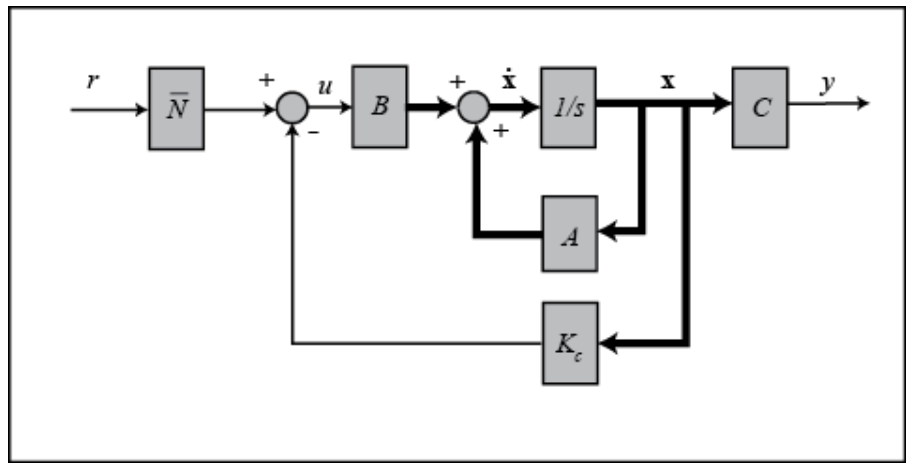

desiredSteadyState = 0.1; 
newSteadyState = 0.0769; 
Nbar = desiredSteadyState/newSteadyState; 

linearSystemAnalyzer(dcMotorSS, Nbar*sys_cl);
[y1,tout1] = step(dcMotorSS, 3); 
[y2, tout2] = step(sys_cl*Nbar,3); 
plot(tout1,y1,tout2,y2); 
legend('original system', 'state feedback control'); 
ylabel('angular speed of motor (rad/s)'); 
xlabel('Time (s)')